# Size Batteries for Electric VTOL Drone

In this example, you design the battery configuration to fulfill the range and peak power requirements of an electric VTOL aircraft. First, you define the operation profiles for the takeoff, hover, climb, cruise, and landing phases. These phases each have distinct energy demands. Then you design the battery configuration to meet these demands.

Copyright 2025 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('EVTOLDesignOverview.html')).

## Model

Open the model` EVTOLTiltrotor.`

open_system('EVTOLTiltrotor');

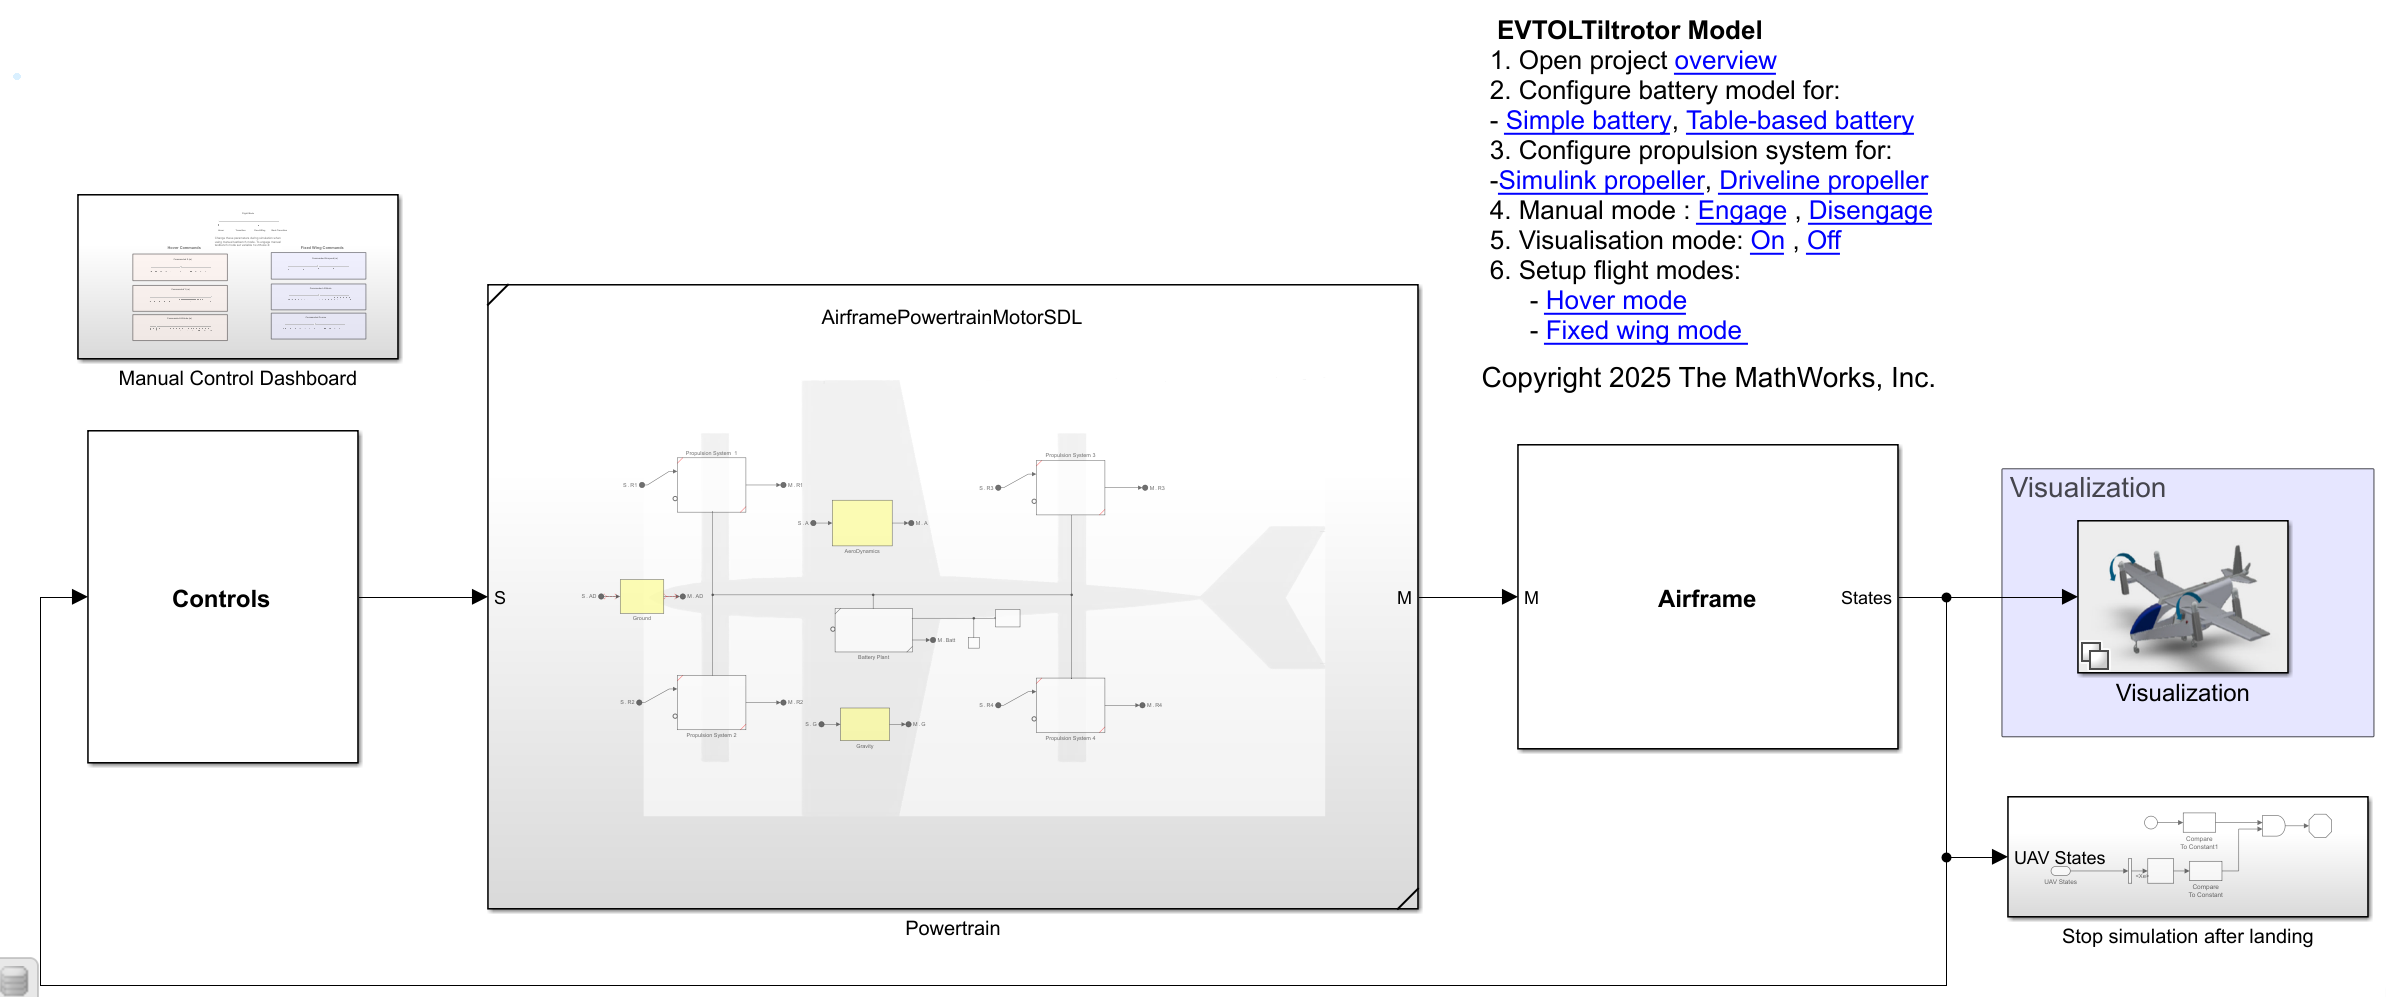

The model represents a vertical take-off and landing (VTOL) aircraft equipped with an electric powertrain. This aircraft features four propellers, each driven by a motor powered by the battery. Two propellers positioned in front of the wings and two at the rear. For more information about the forces acting on the vehicle, see [ModelOverview](matlab:open('ModelOverview.mlx')).

## Battery Sizing 

For the energy calculations in this example, you use a Battery block to model simplified battery with a constant voltage across it. The battery provides power to the four motors that drive the propellers.

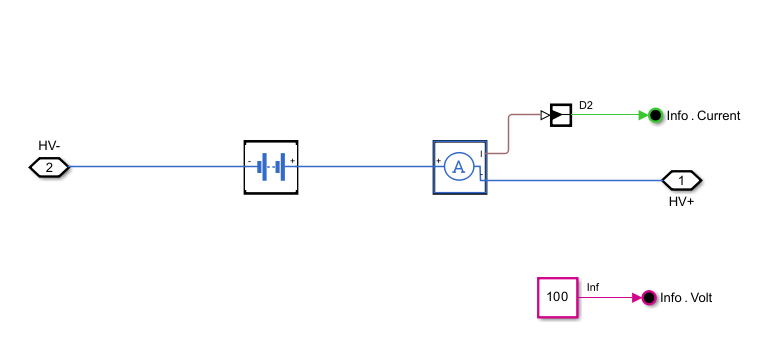 

You vary the battery capacity to analyze how the effective range and energy consumption change. Increasing the battery capacity, at constant energy density, increases the mass of the battery and the gravitational force acting on the aircraft. This increase in the gravitational force consumes energy during flight and acts to reduce the additional range due to the capacity increase.

## Analyze Energy Consumption 

You analyze various simulation runs for different flight modes. In city mode, the simulation encompasses a complete flight sequence, starting from hover mode, transitioning to fixed flight, and then returning to hover mode, thereby covering all flight modes. In full hover mode, you examine the battery consumption as the aircraft follows the flight path without switching to fixed flight mode. In this workflow we vary the battery from 300 Wh to 2000 Wh with step of 100 Wh, assume the gravimetric density of the battery as 180 Wh/kg and update the aircraft mass. Inertia of aircraft is assumed to be uniform and increase in mass is also assumed to be uniform in the `6DOF (Euler Angles)` block. 

Setup the plant and parameters for analysis.

SetupPlant;

Initialized VTOL model.


SetupCityMission;
battery.GravDensity = 180;     % Gravimetric density of battery (Wh/kg)
percWeightGain = 1;            % scaling factor for change in aircraft weight from base mass
baseMass = uavParam.geom.mass; % Aircraft base mass (kg) , 6.023 Kg
capacityRange = 300:100:2000;  % Battery capacity range (Wh)
angleOfAttack = [];            %#ok<*NASGU> % Aircraft angle of attack (deg)

#### Hover Flight Simulation

Energy consumption in hover mode is greater than in cruise mode. In hover mode, a VTOL aircraft needs to produce an upward force equal to its weight to counteract gravity. This demands significant energy because there is no aerodynamic lift from forward motion so the rotors or fans must work much harder to maintain altitude. A  flight path with takeoff, landing, forward and sideways motion is simulated. To get forward motion the front motor are tilted and for sideways motion a roll comand is generated for the motors.

Vary the battery capacity from 300 Wh to 2000 Wh to determine the energy consumed per meter and the range of the aircraft. To calculate the mass of the aircraft, calculate the battery mass from the gravimetric density of the battery and add the base mass to the battery mass. 

Setup the model for hover mode configurationand set a flight path.

SetupHoverConfiguration; 
SetupHoverGuidanceMission; % Flight path for Hover flight 

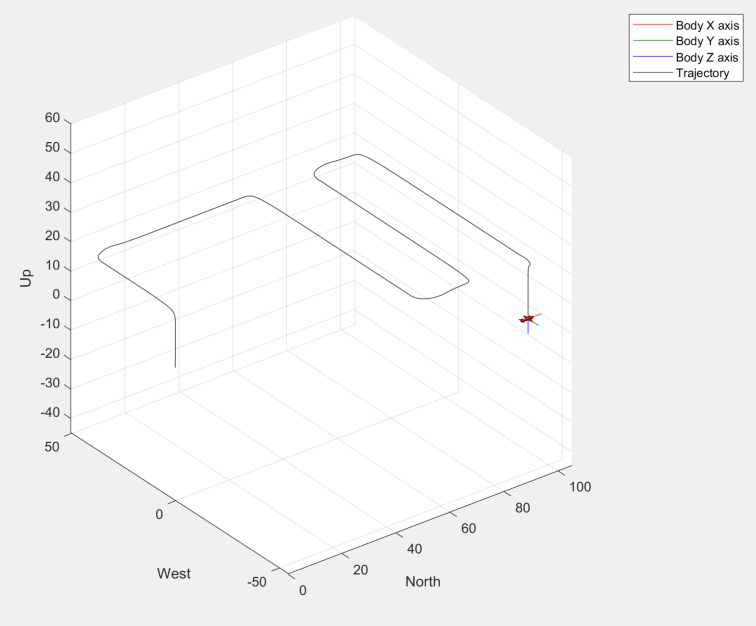

The simulation can take some time. For this example, you can instead load the simulation result from mat file. To execute the simulation, click on the checkbox below.

runHoverSim = false; % Check box to run simulation or load from results from mat file
if runHoverSim
    [rangeHover, mileageHover, ~] = flightModeSimulation(CapacityRange=capacityRange, ...
    BaseMass=baseMass,GravDensity=battery.GravDensity);
else
    load("BatterySizingData.mat","rangeHover","mileageHover");
end

#### Fixed Flight Simulation

Calculate the energy consumed per meter and the range of the aircraft in fixed flight mode. This mode is more energy-efficient as lift is primarily generated by the wings rather than the rotors which allows aircraft to cover longer distances. A flight path of straigh flight at an alttitude of 20 m  which then goes into an orbit is simulated. 

The battery capacity and aircraft weight are configured similarly to the hover mode. As the battery size increases, the aircraft's weight also rises, demanding more lift to maintain flight. To generate this additional lift, the aircraft may need to operate at a higher AoA. However, exceeding the critical AoA can lead to and lift is significantly reduced.

SetupFixedWingConfiguration;
SetupFixedWingGuidanceMission; % Flight path for fixed wing flight 

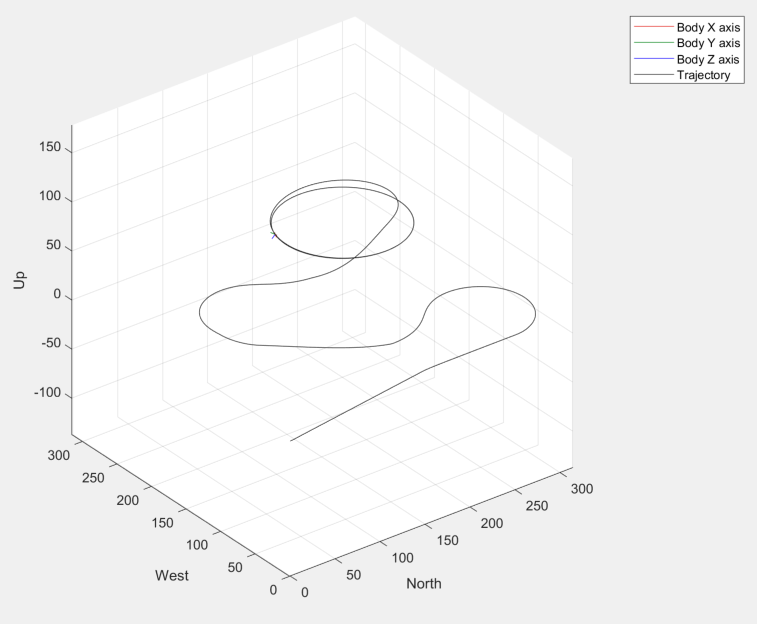

The simulation can take some time. For this example, you can instead load the simulation result from mat file. To execute the simulation, click on the checkbox below.

runFixedWingSim = false;% Check box to run simulation or load from results from mat file
if runFixedWingSim
    [rangeFixed, mileageFixed, angleOfAttack] = flightModeSimulation(CapacityRange=capacityRange, ...
    BaseMass=baseMass,GravDensity=battery.GravDensity);
else
    load("BatterySizingData.mat","rangeFixed","mileageFixed","angleOfAttack");

end

#### Hover Hold

Energy consumption in the aircraft in takeoff and to hold a position in hover mode is also a factor in consideration. For hover lift setup the plant in manual mode

SetupHoverConfiguration;
SetupHoverManual;

% Set Time for Simulation
myDictionaryObj = Simulink.data.dictionary.open('VTOLDynamicsData.sldd');
dDataSectObj = getSection(myDictionaryObj,'Design Data');
simTimeParam = getEntry(dDataSectObj,'simTime');
setValue(simTimeParam,20);
%% Hover mode for Takeoff and landing
% Reset multicopter commands to 0 for linearization.
set_param([mdl '/Manual Control Dashboard/Slider1'],'Value','200')
set_param([mdl '/Manual Control Dashboard/Slider2'],'Value','0');
set_param([mdl '/Manual Control Dashboard/Slider3'],'Value','0');

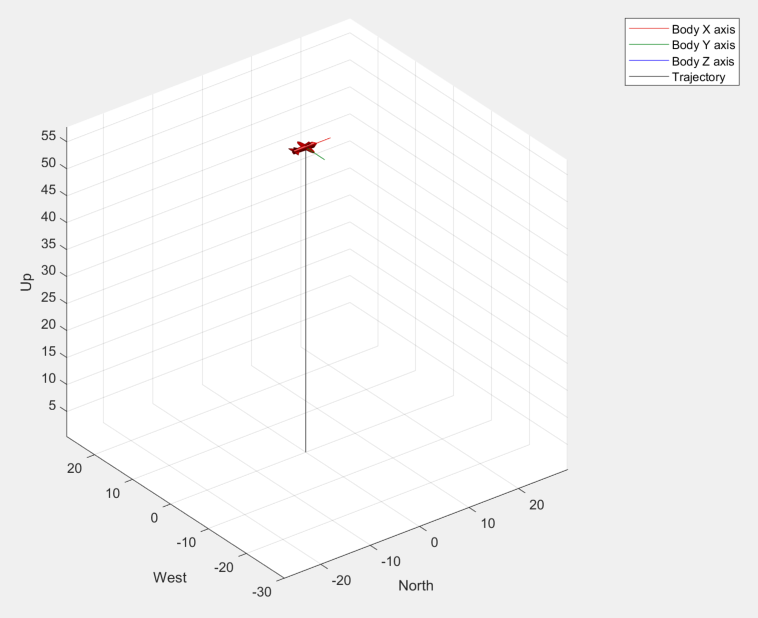

The simulation can take some time. For this example, you can instead load the simulation result from mat file. To execute the simulation, click on the checkbox below.

runTakeoffSim = false; % Check box to run simulation or load from results from mat file
if runTakeoffSim
    [rangeTakeOff, mileageTakeOff, ~] = flightModeSimulation(CapacityRange=capacityRange, ...
    BaseMass=baseMass,GravDensity=battery.GravDensity);
else
    load("BatterySizingData.mat","rangeTakeOff","mileageTakeOff");
end

For Hover hold mode  the energy is consumed per unit time to maintain its hold position.

%% Hover mode for hold position
% Reset multicopter commands to 0 for linearization.
set_param([mdl '/Manual Control Dashboard/Slider1'],'Value','20')
set_param([mdl '/Manual Control Dashboard/Slider2'],'Value','0');
set_param([mdl '/Manual Control Dashboard/Slider3'],'Value','0');

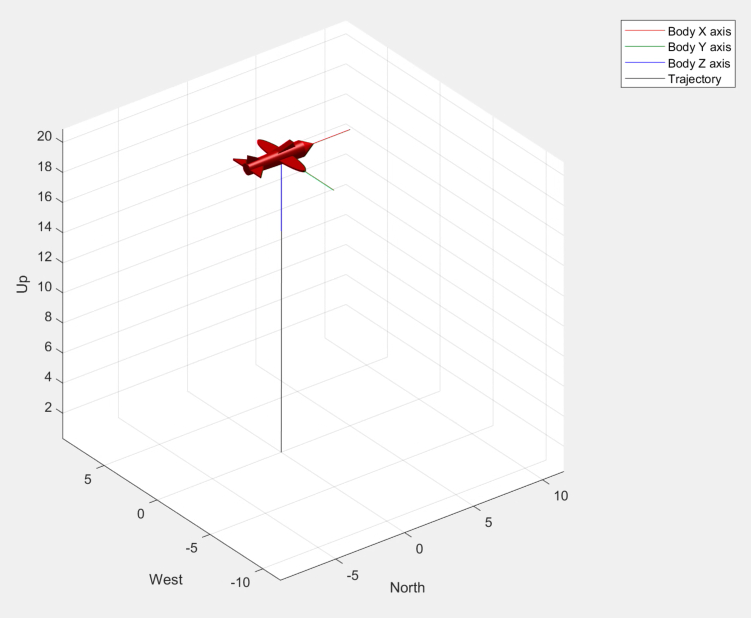

To execute the simulation, click on the checkbox below.

runHoldSim = false; % Check box to run simulation or load from results from mat file
if runHoldSim
    [rangeHold, mileageHold, ~] = flightModeSimulation(CapacityRange=capacityRange, ...
    BaseMass=baseMass,GravDensity=battery.GravDensity,RangeType = "Time");
else
    load("BatterySizingData.mat","rangeHold","mileageHold");
end

## Results

To calculate the average flight time of the aircraft, divide the total energy capacity of the battery by the average power consumption. Since energy consumption differs across various phases of VTOL flight, compute the average power consumption by considering the expected time or distance for each phase. Utilize data from VTOL phase simulations, which provide information on energy consumption per unit distance and time, to perform this calculation.

Plot the range against battery capacity in hover mode.

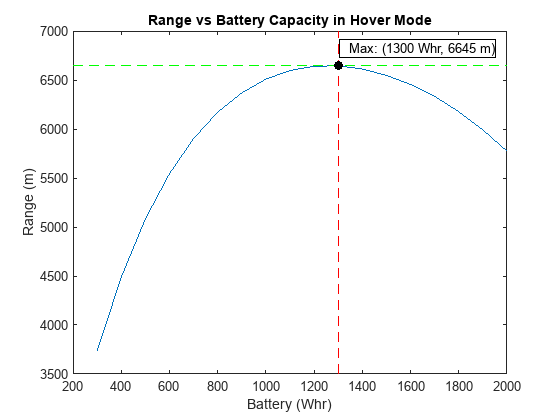

plot(capacityRange,rangeHover)
xlabel('Battery (Whr)')
ylabel('Range (m)')
% Define the point of interest
[y_point,index]= max(rangeHover);
x_point = capacityRange(index);
line([x_point x_point], ylim, 'Color', 'r', 'LineStyle', '--');
line(xlim, [y_point y_point], 'Color', 'g', 'LineStyle', '--');
hold on;
% Add a text bubble at the maximum point
text(x_point+10, y_point+100, sprintf('  Max: (%.f Whr, %.f m)', x_point, y_point), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', ...
    'BackgroundColor', 'w', 'EdgeColor', 'k', 'Margin',1);
plot(x_point, y_point, 'ko', 'MarkerFaceColor', 'k');
title('Range vs Battery Capacity in Hover Mode')
hold off;

In fixed flight mode, particularly during cruise, the energy consumption per unit distance is influenced by several factors. While battery capacity and motor efficiency are important, the range of an electric aircraft is also affected by maneuverability at cruise speed. A key factor influencing this maneuverability is the angle of attack (AoA).

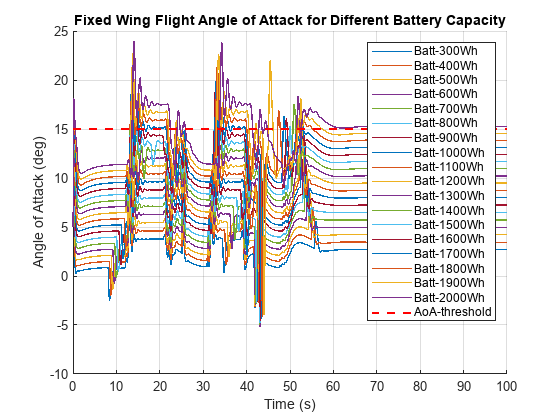


simAttackAnglePlotter(angleOfAttack,capacityRange);
hold on;
title('Angle of Attack in Cruise Flight for Battaery Capacity')
xlabel('Time (s)')
ylabel('Angle of Attack (deg)')
legend


% Define the y-value for the angle of attack(AoA) threshold
y_horizontal = 15; % Threshold set as 15 degrees for AoA

% Add the dashed horizontal line
plot(angleOfAttack(1,1).Time, y_horizontal * ones(size(angleOfAttack(1,1).Time)), ...
    'r--', 'LineWidth', 1.5,DisplayName='AoA-threshold');

% Customize the plot
title('Fixed Wing Flight Angle of Attack for Different Battery Capacity');
grid on;
hold off;

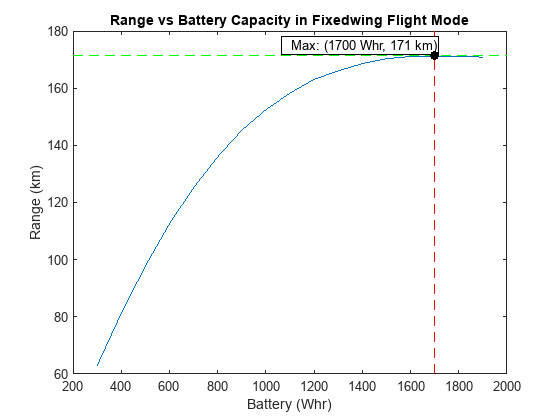

% Battery capacity where AoA in orbit is more than threshold 
% Threshold value for AoA set as 15 degrees
maxCapacityIndex = getMaxCapacityFixedWing(angleOfAttack,15);
if isempty(maxCapacityIndex)
    maxCapacityIndex = size(capacityRange,2) +1;
end
plot(capacityRange(1:maxCapacityIndex-1),rangeFixed(1:maxCapacityIndex-1)/1000)
xlabel('Battery (Whr)')
ylabel('Range (km)')
% Define the point of interest
[y_point,index]= max(rangeFixed(1:maxCapacityIndex-1)/1000);
x_point = capacityRange(index);
line([x_point x_point], ylim, 'Color', 'r', 'LineStyle', '--');
line(xlim, [y_point y_point], 'Color', 'g', 'LineStyle', '--');
hold on;
% Add a text bubble at the maximum point
text(x_point+10, y_point+1, sprintf('  Max: (%.f Whr, %.f km)', x_point, y_point), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', ...
    'BackgroundColor', 'w', 'EdgeColor', 'k', 'Margin',1);
plot(x_point, y_point, 'ko', 'MarkerFaceColor', 'k');
title('Range vs Battery Capacity in Fixedwing Flight Mode')
hold off;

VTOL aircraft can hold a position hover mode and needs constant thrust to maintain it. 

Plot the fligh time in hover hold postition against battery capacity

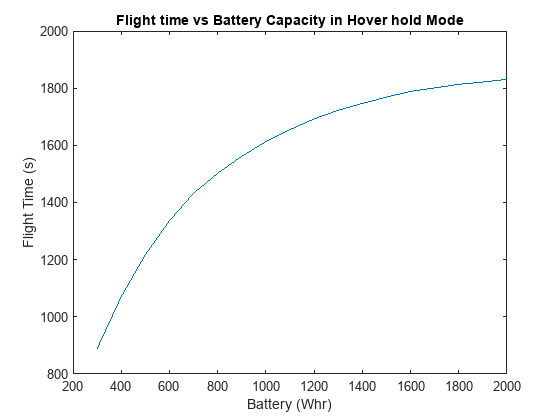

plot(capacityRange,rangeHold)
xlabel('Battery (Whr)')
ylabel('Flight Time (s)')
title('Flight time vs Battery Capacity in Hover hold Mode')

You calculate the duration for which the aircraft can maintain its position in hold mode. You can use this information to estimate the energy consumed during the takeoff and landing phases of flight operations.

## Estimate The Range

 By combining these calculations with those from cruise and other phases, you can determine the average energy consumption for any given flight path and calculate the range of the aircraft. For a flight path of 1000 m with 20% in hover mode, 80% in cruise flight mode and 2 min in hover hold mode at a height of 15 meters, the number of trip for battery capacity of 300 Wh to 2000 Wh and with 180 Wh/kg energy density is shown below below. In this calculation we are not taking cruise ascent and descent into consideration.

Set flight path data

flightPath.height   =  15;                   % Height for cruise (m)
flightPath.Distance    =  1000;              % Range (m)
flightPath.holdTime =  120;                  % flight hold in hover (s)
flightPath.fixedWingRatio = 0.8;             % Ratio of flight path in fixed Wing mode
% structure for mileage variable
mileage = struct("mileageTakeoff",mileageTakeOff,"mileageHover",mileageHover,...
    "mileageFixed",mileageFixed,"mileageHold",mileageHold);  
% structure for range variable
range = struct("rangeTakeoff",rangeTakeOff,"rangeHover",rangeHover,...
    "rangeFixed",rangeFixed,"rangeHold",rangeHold);  
% Clear variables from workspace
clear mileageTakeOff mileageHover mileageFixed mileageHold rangeTakeOff ...
    rangeHover rangeFixed rangeHold rangeData

Calculate number of trips possible for the flight path defined above for varying battery capacity.

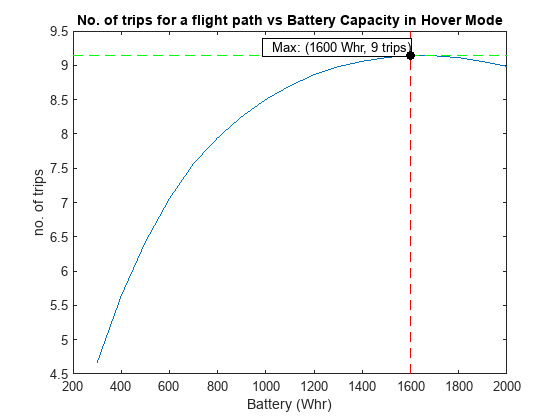

tripsDone = getFlightTripBatterySizing(mileage,flightPath,capacityRange);
plot(capacityRange,tripsDone)
xlabel('Battery (Whr)')
ylabel('no. of trips')
% Define the point of interest
[y_point,index]= max(tripsDone);
x_point = capacityRange(index);
line([x_point x_point], ylim, 'Color', 'r', 'LineStyle', '--');
line(xlim, [y_point y_point], 'Color', 'g', 'LineStyle', '--');
hold on;
% Add a text bubble at the maximum point
text(x_point, y_point, sprintf('  Max: (%.f Whr, %.f trips)', x_point, y_point), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', ...
    'BackgroundColor', 'w', 'EdgeColor', 'k', 'Margin',1);
plot(x_point, y_point, 'ko', 'MarkerFaceColor', 'k');
title('No. of trips for a flight path vs Battery Capacity in Hover Mode')
hold off;

For the current flight path the drone can do maximum 9 trips for battery capacity of 1600 Whr.

## See Also

Motor control tuning workflow [MotorControlTuning](matlab:open('MotorControlTuning.mlx'))